# SLCO4A - Aula Prática 4

## Sinais

### Representação de sinais

#### Sinal degrau


$$u\left(t\right)=\left\lbrace \begin{array}{ll}
1 & t\ge 0\\
0 & t<0
\end{array}\right.$$


*Primeiro método*

t = 10:0.1:10;
u= heaviside(t)

u = 1

*Segundo método*

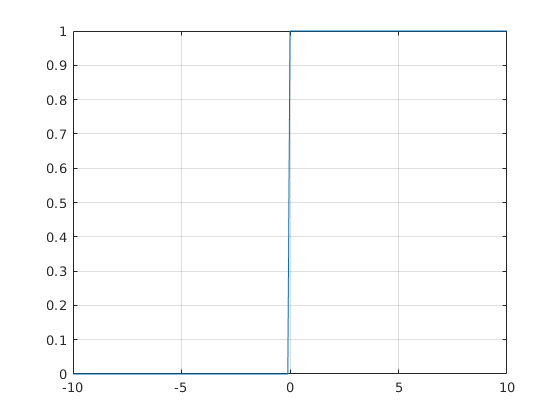

t1 = -10:0.1:-0.1;
t2 = 0:0.1:10;
u1 = zeros(size(t1));
u2 = ones(size(t2));
t = [t1, t2];
u = [u1, u2];
plot(t,u)
grid on

*Terceiro método*

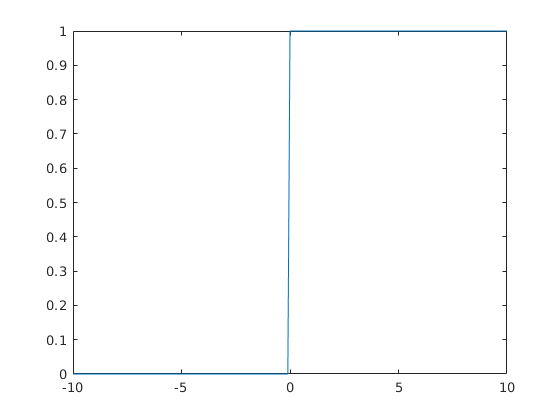

t = -10:0.1:10;
ustep = t>=0;
plot(t, ustep)

#### Sinal impulso unitário ou função delta de Dirac $\delta \left(t\right)$

$\int_{-\infty }^{\infty } f\left(t\right)\delta \left(t\right)=1$, se $f\left(t\right)=1$, $\forall t\in \Re$ então $\int_{-\infty }^{\infty } \delta \left(t\right)=1$

*Primeiro método*

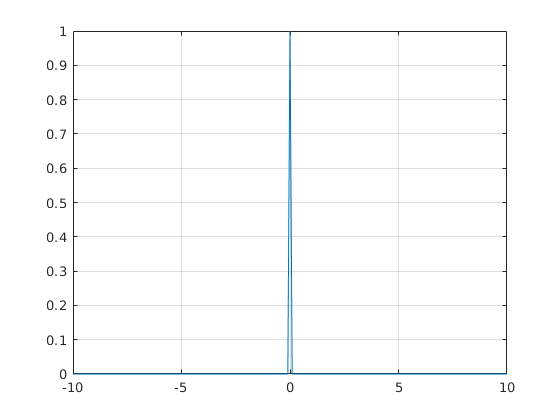

t1 = -10:0.1:-0.1;
t2 = 0;
t3 = 0.1:0.1:10;
d1 = zeros(size(t1));
d2 = 1;
d3 = zeros(size(t3));
t = [t1 t2 t3];
d = [d1 d2 d3];
plot(t, d)
grid on

*Segundo método*

t = -10:0.1:10;
d = t==0;
plot(t,d)
grid on

*Terceiro método*

t = -10:0.1:10;
d = gauspuls(t);
plot(t, d)
grid on 

*Quarto método*


$$\delta \left(t\right)=\left\lbrace \begin{array}{ll}
\infty  & t=0\\
0 & t\not= 0
\end{array}\right.$$


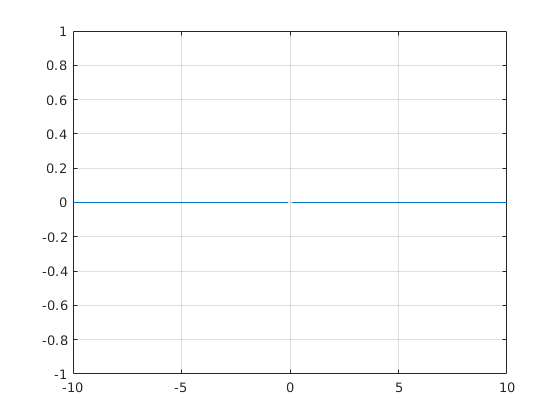

t = -10:0.1:10;
d = dirac(t);
plot(t, d)
grid on

*Propriedade da integral*


$$\int_{-\infty }^{\infty } \delta \left(t\right)=1$$


syms t 
d = dirac(t);
res = int(d, t, -inf, inf);

#### Sinal rampa


$$r\left(t\right)=t\cdot u\left(t\right)=\left\lbrace \begin{array}{ll}
t & t\ge 0\\
0 & t<0
\end{array}\right.$$


*Primeiro método*

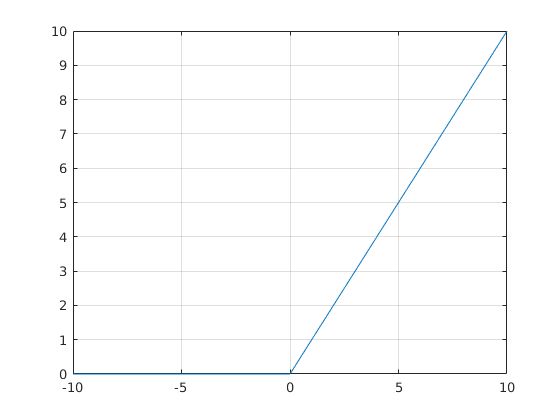

t = -10:0.1:10;
r = t.*heaviside(t);
plot(t, r)
grid on

*Segundo método*

t1 = -10:0.1:-0.1;
t2 = 0:0.1:10;
r1 = zeros(size(t1));
r2 = t2;
t = [t1 t2];
r = [r1 r2];
plot(t, r)
grid on

*Terceiro método*

t = -10:0.1:10;
r = (t>=0).*t;
plot(t, r)
grid on

#### Sinal pulso retangular


$$\textrm{pT}\left(t\right)=u\left(t+\frac{T}{2}\right)-u\left(t-\frac{T}{2}\right)=\left\lbrace \begin{array}{ll}
1 & -\frac{T}{2}\le \;t\le \frac{T}{2}\\
0 & \textrm{cc}
\end{array}\right.$$


a) Considere $T=4$, obtenha a representação gráfica de $\textrm{p4}\left(t\right)\ldotp$

*Primeiro método*

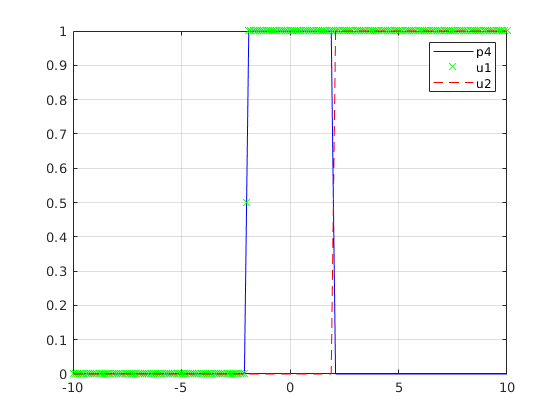

t = -10:0.1:10;
u1 = heaviside(t+2);
u2 = heaviside(t-2);
p4 = u1 - u2;
figure
plot(t, p4, 'b')
hold on 
plot(t,u1, 'gx', t, u2, 'r--')
grid on
legend('p4', 'u1', 'u2')

*Segundo método*

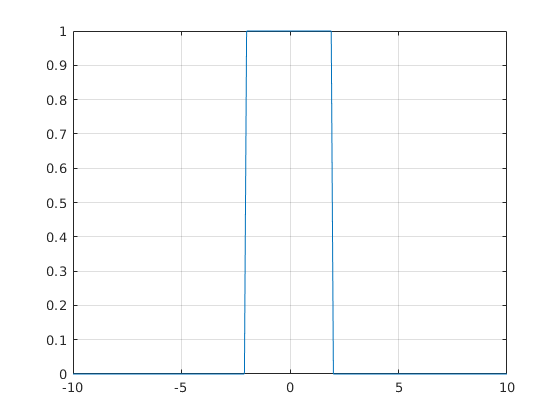

t = -10:0.1:10;
s = rectpuls(t, 4);
figure
plot(t, s)
grid on

*Terceiro método*

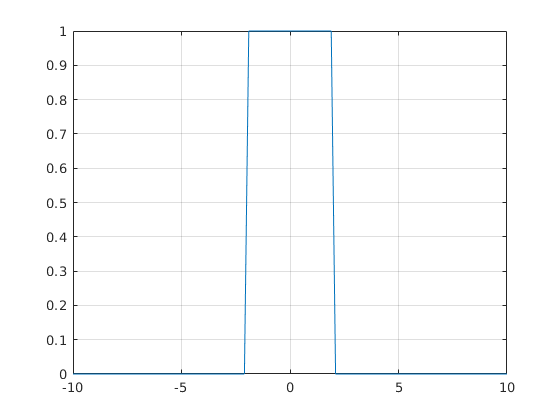

t = -10:0.1:10;
s = rectangularPulse(-2, 2, t);
figure
plot(t, s)
grid on

#### Sinal triangular

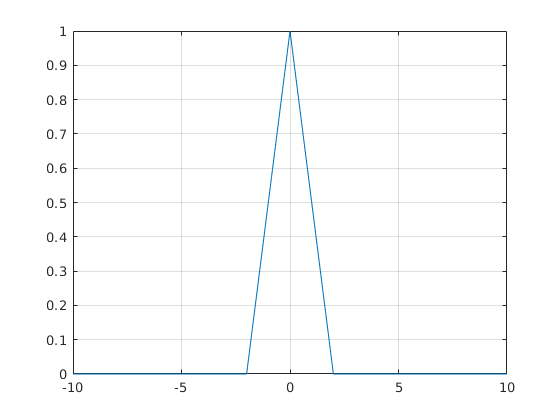

t = -10:0.1:10;
tri = triangularPulse(-2,2,t);
plot(t, tri)
grid on

#### Sinal onda quadrada

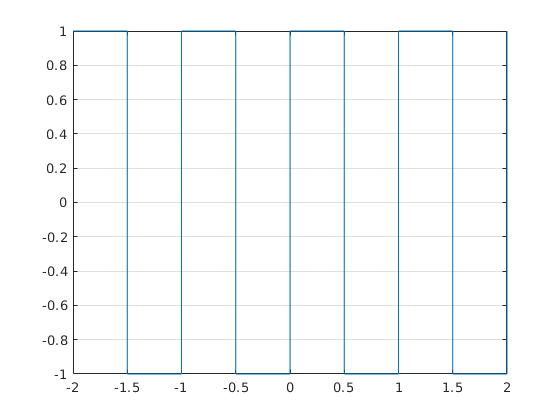

t = -2:0.0001:2;
s = square(2*pi*t);
plot(t, s)
grid on

#### Sinal exponencial complexa


$${\mathrm{Ae}}^{j\Omega t+\theta } =\mathrm{Acos}\left(\Omega \;t+\theta \;\right)+j\;\mathrm{sen}\left(\Omega \;t+\theta \;\right)$$


a) Obtenha a representação da parte real e imaginária do sinal $y\left(t\right)={2e}^{j\pi \;t+\frac{\pi }{3}\;} \;$no intervalo de um período

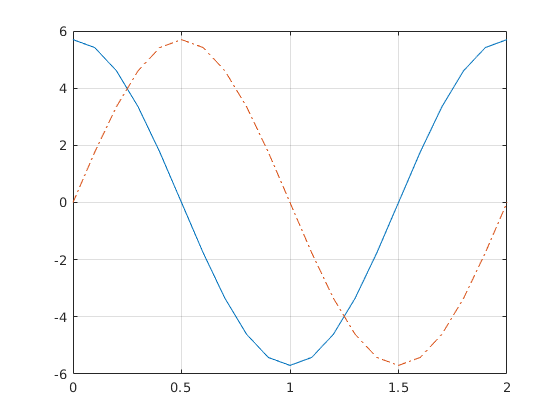

T = 2*pi/pi;
t = 0:0.1:T;
y_re = real(2*exp(j*pi*t+pi/3));
y_im = imag(2*exp(j*pi*t+pi/3));
plot(t, y_re, t, y_im, '-.')
grid on

### Propriedades de sinais

#### Sinais periódicos


$$x\left(t\right)=x\left(t+k\;T\right),\forall t\in \Re$$


a) Verifique se o sinal $x\left(t\right)=\sin \left(t\right)$é periódico.

Computando o período, obtém-se que $T=\frac{2\;\pi }{1}=2\pi$. Analisando a periodicidade para $1\le k\le 10$ e $1\le t\le 5$.

t = 1:5;
x = sin(t);
T = 2*pi;
for k =1:10
    xk = sin(t+k*T)
end

xk =     0.8415    0.9093    0.1411   -0.7568   -0.9589


xk =     0.8415    0.9093    0.1411   -0.7568   -0.9589


xk =     0.8415    0.9093    0.1411   -0.7568   -0.9589


xk =     0.8415    0.9093    0.1411   -0.7568   -0.9589


xk =     0.8415    0.9093    0.1411   -0.7568   -0.9589


xk =     0.8415    0.9093    0.1411   -0.7568   -0.9589


xk =     0.8415    0.9093    0.1411   -0.7568   -0.9589


xk =     0.8415    0.9093    0.1411   -0.7568   -0.9589


xk =     0.8415    0.9093    0.1411   -0.7568   -0.9589


xk =     0.8415    0.9093    0.1411   -0.7568   -0.9589


b) Construindo sinais periódicos

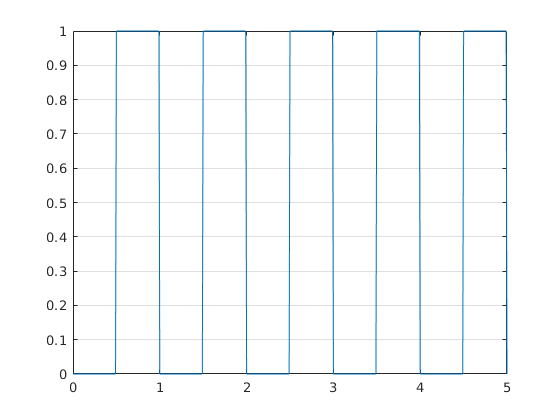

[s,t] = gensig('square', 1, 5, 0.01);
figure
plot(t,s)
grid on

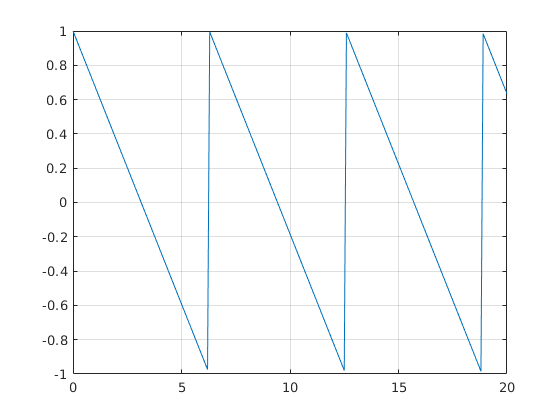

t = 0:0.1:20;
sw = sawtooth(t, 0);
plot(t, sw)
grid on

#### Sinais causais e não causais

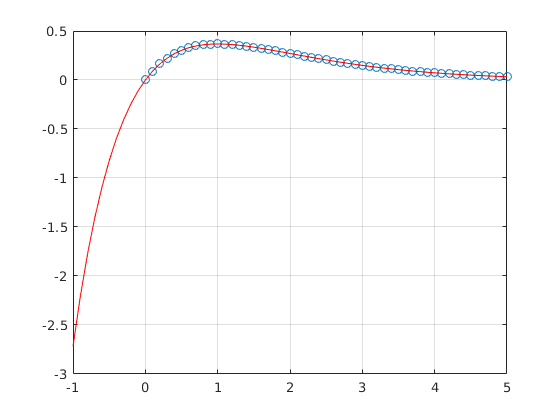

t1 = 0:0.1:5;
t2 = -1:0.1:5;
x1 = t1.*exp(-t1);
x2 = t2.*exp(-t2);
plot(t1, x1, '-o', t2, x2, '-r')
grid on

#### Sinais do tipo par e ímpar

a) Verifique se os sinais $x\left(t\right)=t^2$ e $y\left(t\right)=t^3$ são do tipo par ou ímpar.

t1 = 0:4:4;
t1 = 0:-4:-4;
x1 = t1.^2;
x2 = t2.^2;
y1 = t1.^3;
y2 = t2.^3;

#### Sinais determínistico e estocástico

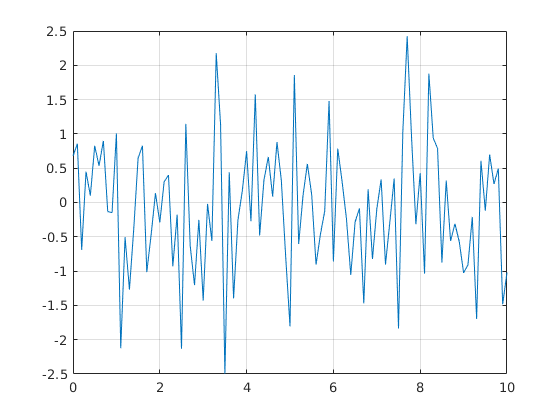

t = 0:0.1:10;
x1 = randn(size(t));
plot(t, x1)
grid on

### Transformação de sinais

#### Deslocamento temporal

a) Considere o sinal degrau unitário dado por $u\left(t-t_0 \right)$, $t_0 =2$. Obtenha a representação temporal de $u\left(t-2\right)$.

*Primeiro método*

*Segundo método*

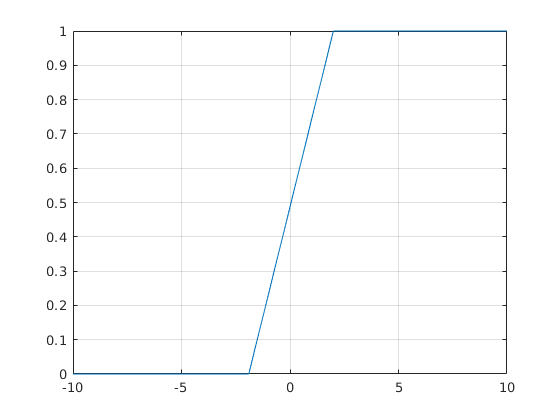

t1 = -10:0.1:-1.9;
t2 = 2:0.1:10;
u1 = zeros(size(t1));
u2 = ones(size(t2));
t = [t1, t2];
u = [u1, u2];
plot(t,u)
grid on

b) Obtenha a representação gráfica de $\delta \left(t+2\right)$

c) Obtenha a representação gráfica da função rampa unitária, sendo $t_0 =1$: $r\left(t-t_0 \right)=\left(t-t_0 \right)u\left(t-t_0 \right)=\left\lbrace \begin{array}{ll}
t-t_0  & t\ge t_0 \\
0 & t<t_0 
\end{array}\right.$

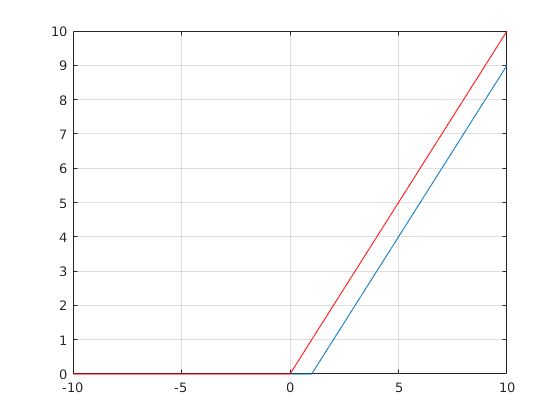

t = -10:0.1:10;
r1 = (t-1).*heaviside(t-1);
r2 = (t).*heaviside(t);
plot(t,r1, t, r2, 'r')
grid on

#### Reversão temporal ou reflexão

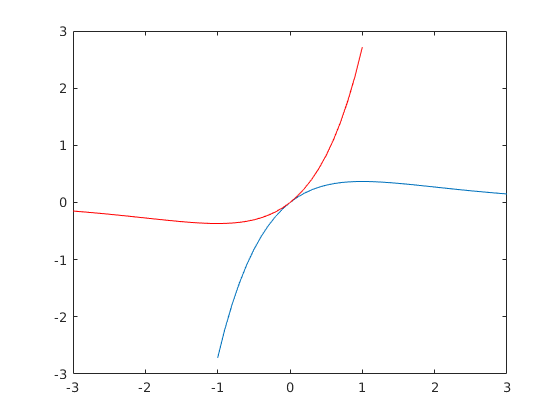

t = -1:0.1:3;
x = t.*exp(-t);
plot(t,x, -t, x, 'r')

#### Escalonamento temporal

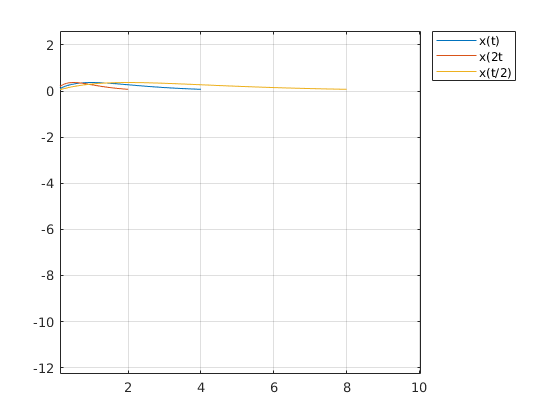

t = -2:0.1:4;
x = t.*exp(-t);
figure
plot(t, x)
hold on 

a=2;
plot((1/a)*t, x)
a=0.5;
plot((1/a)*t, x)
grid on
legend('x(t)', 'x(2t', 'x(t/2)', 'Location', 'bestoutside')